# AI621 A3 : Image Blending

20215584 Wonjoon Chang

Youtube: https://youtu.be/gUB_7NJi8VY

## (1) Toy Problem

toyim = im2double(imread('./data/toy_problem.png'));
[imh, imw, nn] = size(toyim)

imh = 119

imw = 110

nn = 1

im2var = zeros(imh, imw);
im2var(1:imh*imw) = 1:imh*imw;
im2var

im2var =            1         120         239         358         477         596         715         834         953        1072        1191        1310        1429        1548        1667        1786        1905        2024        2143        2262        2381        2500        2619        2738        2857        2976        3095        3214        3333        3452        3571        3690        3809        3928        4047        4166        4285        4404        4523        4642        4761        4880        4999        5118        5237        5356        5475        5594        5713        5832
           2         121         240         359         478         597         716         835         954        1073        1192        1311        1430        1549        1668        1787        1906        2025        2144        2263        2382        2501        2620        2739        2858        2977        3096        3215        3334        3453        3572        3691      

## Initialization

Set variables to represnt the least square problem in matrix form.

M = 2*imw*imh-imh-imw+1;
N = imw*imh;
nzmax = 2*M;
A = sparse([],[],[], M, N, nzmax);
b = zeros(M,1);
s = toyim;

## Solving the least square problem

Construct A and b according to the objective function.

There are three kinds of constraints.

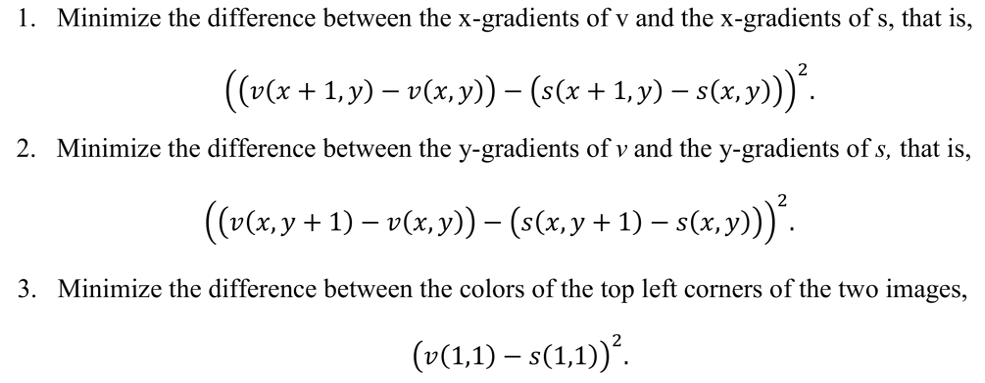

e = 0; % row of A, b

for x = 1:(imw-1)
    for y = 1:imh
        e = e+1;
        A(e, im2var(y,x+1)) = 1;
        A(e, im2var(y,x)) = -1;
        b(e) = s(y,x+1)-s(y,x);
    end
end

for x = 1:imw
    for y = 1:(imh-1)
        e = e+1;
        A(e, im2var(y+1,x)) = 1;
        A(e, im2var(y,x)) = -1;
        b(e) = s(y+1,x)-s(y,x);
    end
end

e = e+1;
A(e, im2var(1,1)) = 1;
b(e) = s(1,1);

v = A \ b;

## Result

The image is successfully reconstucted by using gradient information and the error is very low.

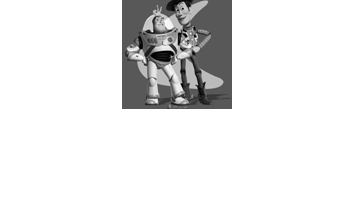

im_out = reshape(v, [imh, imw, nn]);
figure;
imshow(im_out);

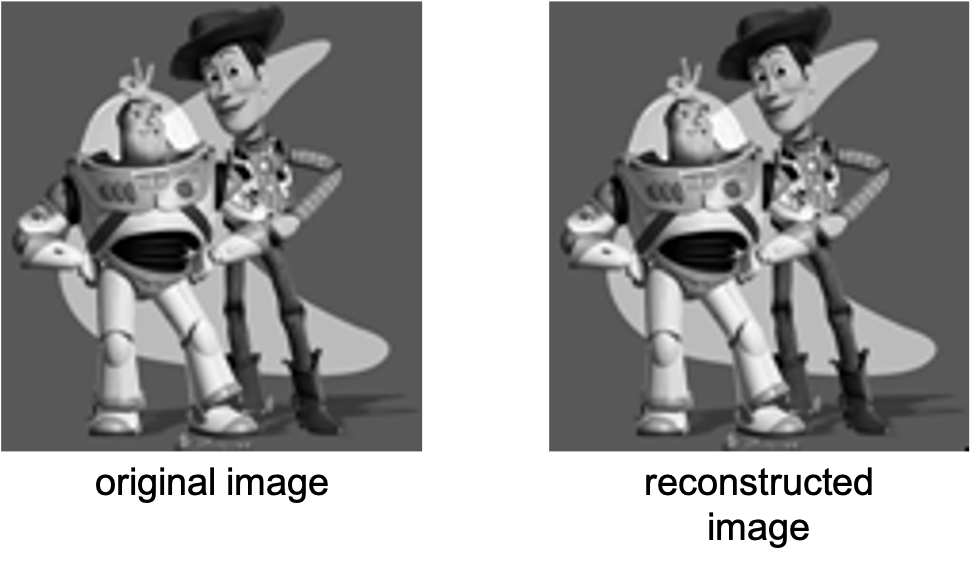

disp(['Error: ' num2str(sqrt(sum(abs(toyim(:) - im_out(:)))))])

Error: 3.6245e-06


imwrite(im_out, './result/toy_recon.png')